# Pràctica 7. Exercici 6

Exercici 5 del document CN_full5.pdf

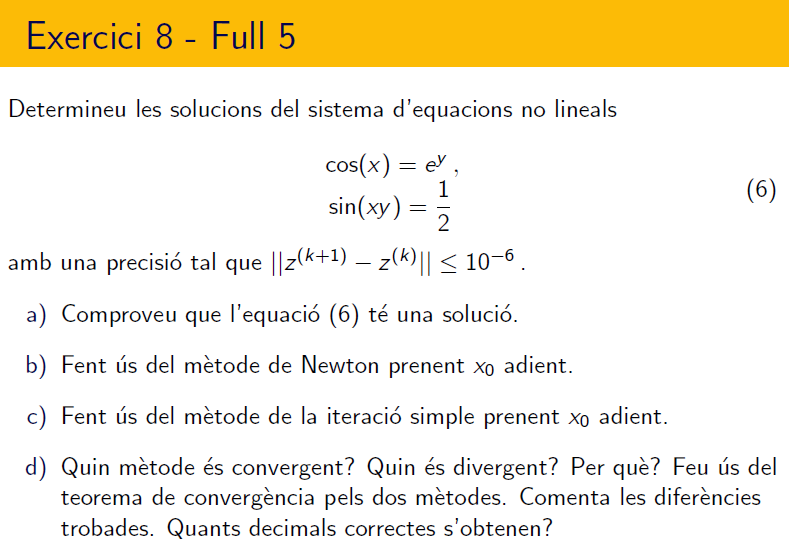

================================================================================

- `Comproveu que el sistema d'equacions té una solució`

F1 = @(x,y)cos(x)-exp(y);
F2 = @(x,y)sin(x*y)-1/2;
fimplicit(F1,[-15 15 -5 0],':r','LineWidth',2)
hold on
fimplicit(F2,[-15 15 -5 0],'--g','LineWidth',2),grid

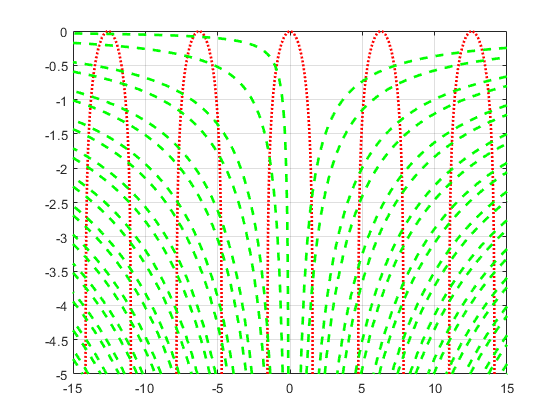

hold off

- `Calculeu iterats pel mètode de Newton, prenent x0 adient fins que `$$\vert\vert
	\mathbf{Z}^{(k+1)}-\mathbf{Z}^{(k)}\vert\vert\le 10^{-6}\,, $$  per $Z = [x,y]^t$

% TODO

- `Calculeu iterats pel mètode de l'iteració simple, prenent x0 adient fins que `$$\vert\vert
	\mathbf{Z}^{(k+1)}-\mathbf{Z}^{(k)}\vert\vert\le 10^{-6}\,, $$ per $Z = [x,y]^t$

G1 = @(x,y)acos(exp(y));
G2 = @(x,y)asin(1/2)/x;
t = [-1 -0.5]';
for k=1:5
    t(1)=G1(t(1),t(2));
    t(2)=G2(t(1),t(2));
    disp([k,t'])
end

            1      0.91911      0.56968

            2 +          0i            0 -      1.171i            0 +    0.44712i

            3 +          0i      0.71756 -    0.61754i      0.41921 +    0.36077i

            4 +          0i      0.45303 -     1.0328i      0.18649 +    0.42516i

            5 +          0i      0.60124 -    0.79292i      0.31792 +    0.41927i



fprintf("No és possible determinar una funció G tal que Z = G(Z) per aquestes equacions")

No és possible determinar una funció G tal que Z = G(Z) per aquestes equacions

- `Compareu els resultats obtinguts amb el resultat de fsolve de MATLAB®. Quants decimals correctes s'obtenen? `

options = optimset('Display','iter'); % show iterations
x0 = [-1, 0]; [x, fval] = fsolve(@myfun,x0,options)


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3        0.461322                          0.96               1
     1          6        0.011478       0.502289         0.0929               1
     2          9     2.06394e-05       0.102757        0.00459            1.26
     3         12     6.22445e-11     0.00446507       7.78e-06            1.26
     4         15     7.37186e-22    7.71393e-06       2.73e-11            1.26

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<<a href = "ma

x =       -0.9547     -0.54844


fval =   -1.7161e-11   -2.104e-11


function F = myfun(x) 
    F(1) = cos(x(1))-exp(x(2));
    F(2) = sin(x(1)*x(2))-1/2;
end